functions = functionsContainer;
Bob = sender;
Alice = receiver;

Bob.makeCliffordGates();
Alice.makeCliffordGates();
Bob.setPermSet();
Alice.setPermSet();

codeword = Bob.messageToBinary("hello")

codeword = 14×1 string array
    "011"
    "010"
    "000"
    "110"
    "010"
    "101"
    "101"
    "100"
    "011"
    "011"
    "000"
    "110"
    "111"
    "100"


encrypted_states = Bob.encrypt(codeword);
decoded = Alice.decode(encrypted_states);

11
11
11
11
11
11
11
11
11
11
11
11
11
11


f = Alice.binaryToMessage(decoded)

011010000110010101101100011011000110111100


f = 'hello'

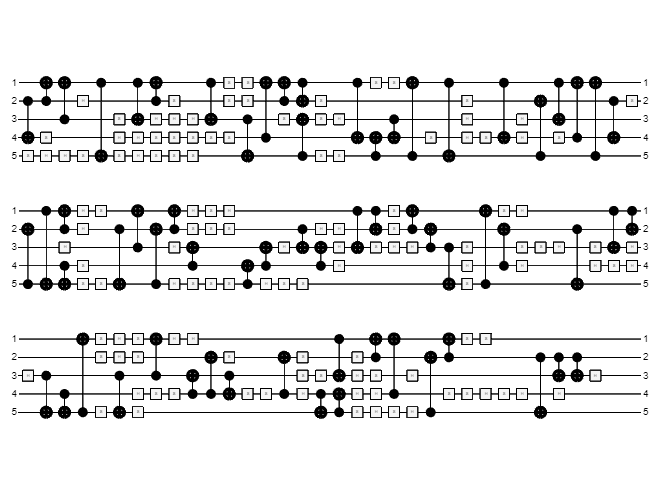


gates = [ Bob.clifford_gates{1}];
C = quantumCircuit(gates);
plot(C);

gates = [ Alice.clifford_gates{1}];
C = quantumCircuit(gates);
plot(C);